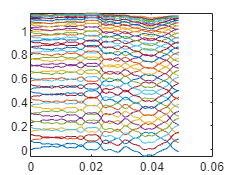

% 1.
Ta = 0.001;
N = 50;
[x,t] = GeraSinal(N,Ta);

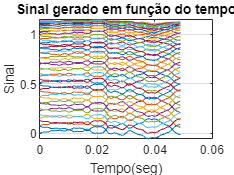

figure(1)
plot(t,x)
title('Sinal gerado em função do tempo')
xlabel('Tempo(seg)')
ylabel('Sinal')
grid

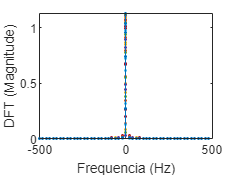


% 2.
figure(2)
[X,f] = Espetro(x,Ta);

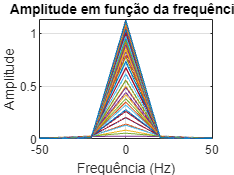

Fa = 1/Ta;
plot(f,abs(X))
xlim([-50,50])
xlabel('Frequência (Hz)')
ylabel('Amplitude')
title('Amplitude em função da frequência')
grid

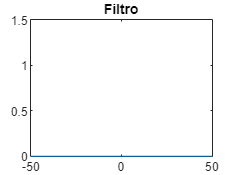



% 3.
fmin = 0;
fmax = 2;

filtro = zeros(1,length(f));
filtro(f>fmin & f<fmax) = 1;
filtro(f>-fmax & f<-fmin) = 1;
filtro = logical(filtro);

figure(3)
plot(f,filtro)
title('Filtro')
xlim([-50,50])
ylim([0,1.5])

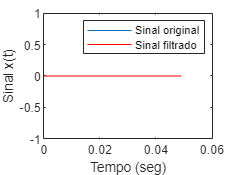


j = 0;
x_filt = X(filtro);
new_x = zeros(length(X),1);
for i = 1:length(filtro)
    if filtro(i) == 1
        j = j + 1;
        new_x(i) = x_filt(j);
    end
end

w = Reconstroi(new_x,f);
figure(1)
hold on
plot(t,w,'r-')
legend('Sinal original','Sinal filtrado')